# Take-Off - Turboprop

#### Reference aircraft

close all; clear all; clc;
N = 50;
h = [0 3000];                                                                 % Altitude
[~,a,~,rho] = atmosisa(h/(3.281));

Aircraft data:

W = 18600;                                                                    % Weight
W = W*9.81;                                                                   % Weight
S = 54.56;                                                                    % Wing area
b_wing = 24.57;                                                               % Wingspan
AR = b_wing^2/S;                                                              % Aspect ratio 
e_TO = 0.85;                                                                  % Oswald's factor in take-off configuration
K_ES = 0.75;                                                                  % Induced drag reduction in ground effect
CL_g = 0.70;                                                                  % Lift coefficient during ground run
CL_MAX_TO = linspace(1.9,3,N);                                                % Maximum lift coefficient
CD0 = 0.02;                                                                   % Drag coefficient at zero lift 
delta_CD0 = 0.015;                                                            % Increase of drag coefficient at zero lift
mu = 0.05;                                                                    % Rolling friction coefficient
K = 1/(pi*AR*e_TO);
eta = 0.85;                                                                   % Shaft efficiency
PI_0 = 2*2050000*eta;                                                         % Maximum take-off power

Two different speeds are calculated: 

Stalling speed:                                $V_{S,\textrm{TO}} =\sqrt{\frac{2\cdot W}{\rho \cdot S\cdot C_{L,\textrm{MAX},\textrm{TO}} }}$                  

Lift off speed:                                  $V_{\textrm{LO}} =K_{V,\textrm{LO}} \cdot V_{S,\textrm{TO}} =1\ldotp 2\cdot V_{S,\textrm{TO}}$    

for i = 1:length(h)
    for j = 1:length(CL_MAX_TO)
        V_s_TO(i,j) = sqrt((2*W)/(rho(i)*S*CL_MAX_TO(j)));                    % Stalling speed
    end
end
K_v_LO = 1.1;
V_LO = K_v_LO*V_s_TO;                                                         % Lift off speed

Thrust is calculated with interpolant function:


$$T=\frac{T}{T_0 }\left(M,h\right)\cdot T_0$$


Drag coefficient is calculated considering the increase due wheels and flaps, induced drag reduction in ground effect and aircraft's lift coefficient during ground roll, which is the same until rotation and detachment: 


$$C_D =C_{\textrm{D0}} +\Delta C_{\textrm{D0}} +\frac{C_{L,g}^2 }{\pi \cdot \textrm{AR}\cdot e_{\textrm{TO}} }\cdot K_{\textrm{ES}}$$



$$D=\frac{1}{2}\cdot \rho \cdot V^2 \cdot S\cdot C_D$$


CD = CD0+delta_CD0+CL_g^2*K;                                                  % Drag coefficient

Lift is calculated using aircraft's lift coefficient during ground roll:


$$L=\frac{1}{2}\cdot \rho \cdot V^2 \cdot S\cdot C_{L,g}$$


Frictional force:


$$F=\mu \left(W-L\right)$$


So ground roll distance is calculated with the integral:


$$S_G =\int_0^{V_{\textrm{LO}} } \frac{g}{W}\cdot \frac{V}{\left\lbrack T\left(V\right)-D\left(V\right)-\mu \left(W-L\left(V\right)\right)\right\rbrack }\textrm{dV}$$


for i = 1:length(h)
    for j = 1:length(CL_MAX_TO)
        fun = @(v) v./((ThrustRatio_TP_TO(v/a(i),h(i))*PI_0/v-...
            (0.5*rho(i)*v.^2*S*CD)-mu*(W-0.5*rho(i)*v.^2*S*CL_g))/(W/9.81));
        S_G(i,j) = integral(fun,0,V_LO(i,j));                                 % Ground roll distance
    end 
end

Speed during airborne:


$$V_{\textrm{air}} =K_{V,\textrm{air}} \cdot V_{S,\textrm{TO}} =1\ldotp 2\cdot V_{S,\textrm{TO}}$$


K_v_air = 1.2;
v_air = K_v_air*V_s_TO;                                                       % Speed during airborne

Load factor during airborne:


$$n_{\textrm{air}} =\frac{L}{W}=\frac{\frac{1}{2}\cdot \rho \cdot {\left(K_{V_{\textrm{air}} } \cdot V_{S\_\textrm{TO}} \right)}^2 \cdot S\cdot \left(K_{\textrm{CL},\textrm{air}} \cdot C_{L,\textrm{MAX},\textrm{TO}} \right)}{W}$$


K_CL_air = 0.9;
n_air = K_v_air^2*K_CL_air;                                                   % Load factori during airborne

Airborne radius:


$$R=\frac{V_{\textrm{air}}^2 }{g\cdot \left(n_{\textrm{air}} -1\right)}$$


for i = 1:length(h)
    for j = 1:N
        R(i,j) = v_air(i,j)^2/((n_air-1)*9.81);                               % Airborne radius
    end
end                                                   
H = 15.24;

To calculate the trajectory angle for overcoming the obstacle, the following relation is considered:


$$\left(R-H\right)=R\cdot \cos \left(\theta_{\textrm{OB}} \right)$$


for i = 1:length(h)
    for j = 1:N
        theta(i,j) = acos(1-H/R(i,j));                                        % Trajectory angle
    end
end

Airborne distance:


$$S_A =R\cdot \sin \left(\theta_{\textrm{OB}} \right)$$


for i = 1:length(h)
    for j = 1:N   
        S_A(i,j) = R(i,j)*sin(theta(i,j));                                    % Airborne distance
    end
end

Total field length:


$$S_{\textrm{TO}} =S_G +S_A$$


S_TO = S_G+S_A;                                                               % Total field length

Graphic:

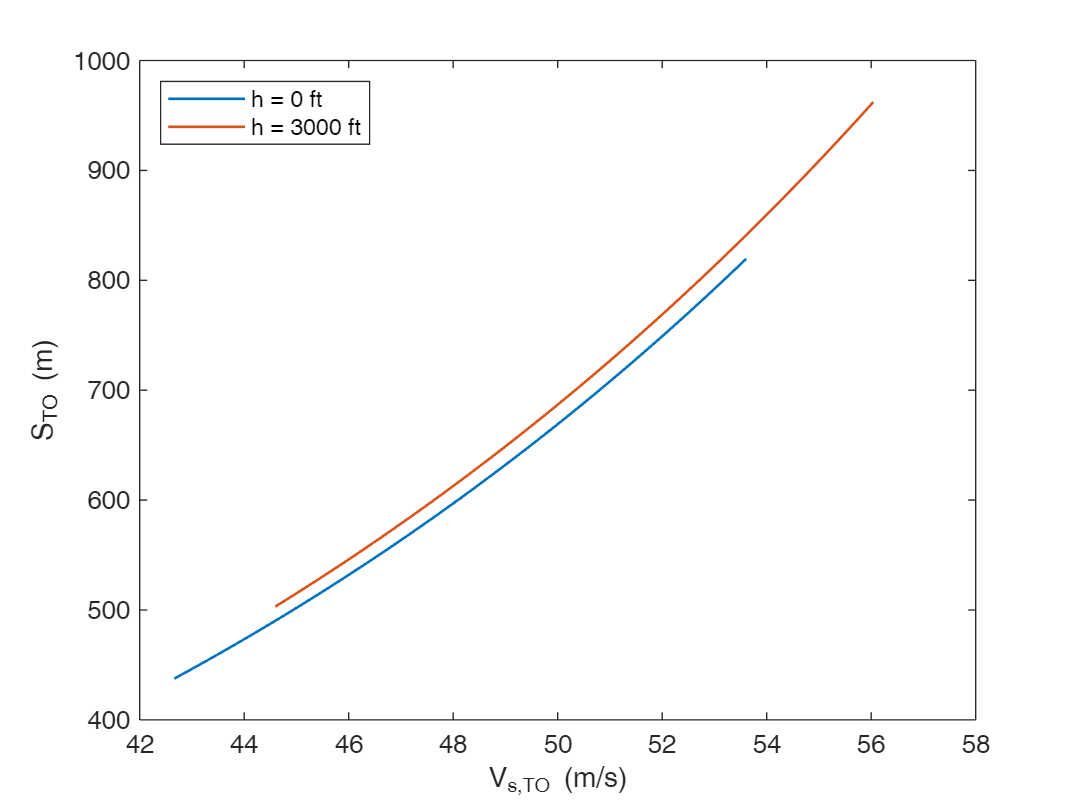

figure;
plot(V_s_TO(1,:),S_TO(1,:),'LineWidth',1); hold on;
plot(V_s_TO(2,:),S_TO(2,:),'LineWidth',1); hold off;
legend('h = 0 ft','h = 3000 ft','location','northwest');
xlabel('V_{s,TO} (m/s)'); ylabel('S_{TO} (m)');

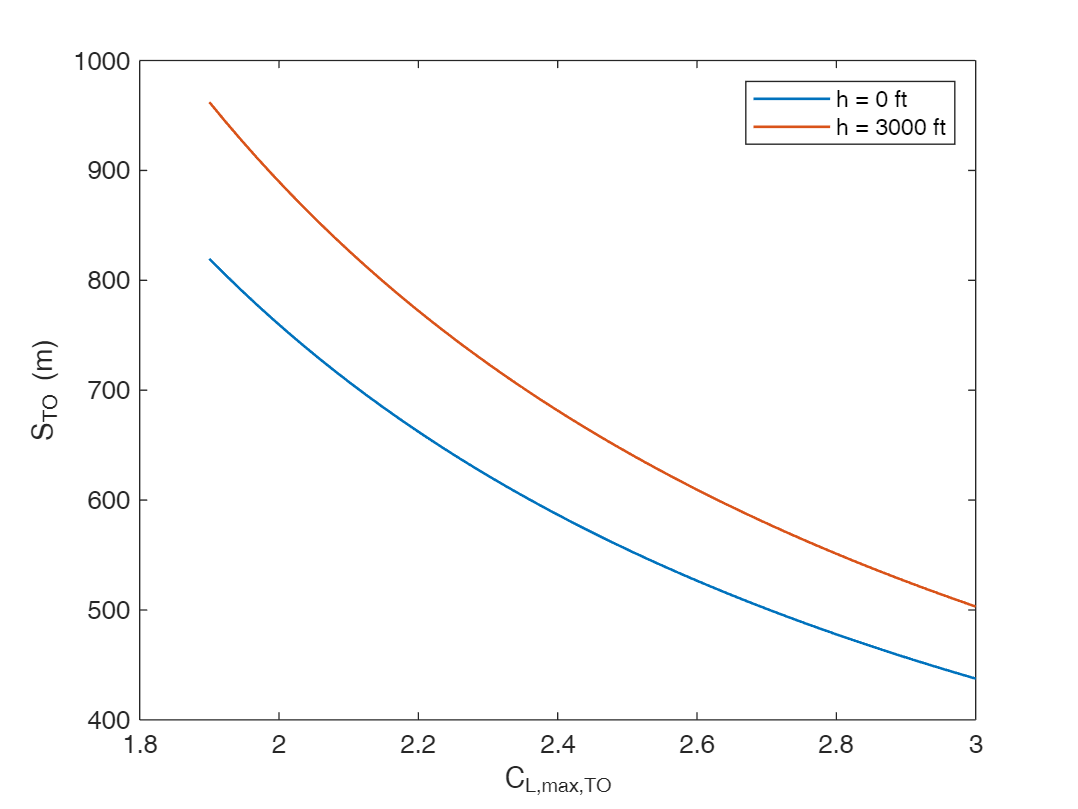

figure;
plot(CL_MAX_TO,S_TO(1,:),'LineWidth',1); hold on;
plot(CL_MAX_TO,S_TO(2,:),'LineWidth',1); hold off;
legend('h = 0 ft','h = 3000 ft');
xlabel('C_{L,max,TO}'); ylabel('S_{TO} (m)');